import matlab.io.hdfeos.*
% clearvars -except study_area;
clear;

disp(">>> Declarando variables...ok")

>>> Declarando variables...ok


%directorio de datos
dir_data = "E:\DATA\";
%Priducto MODIS
producto = 'MOD13Q1';
% Área de estudio
% archivo_kml = "No_cultivo_2";

% archivos_kml=["n_p_1","n_p_2","n_p_3","n_p_4","n_p_5","n_p_6","n_p_7","n_p_8","n_p_9","n_p_10","n_p_11"...
%     ,"n_p_12","n_p_3","n_p_14","n_p_15","n_p_16","n_p_17","n_p_18","n_p_19","n_p_20","n_p_21"...
%     ,"n_p_22","n_p_23","n_p_24","n_p_25","n_p_26","n_p_27","n_p_28","n_p_29","n_p_30","n_p_31"...
%     ,"n_p_32","n_p_33","n_p_34","n_p_35","n_p_36","n_p_37","n_p_38","n_p_39","n_p_40","n_p_41","n_p_42","n_p_43"];

% archivos_kml=["ciudad_1","ciudad_2"]
% archivos_kml=["selva_1","selva_2","selva_3","selva_4","selva_6","selva_7","selva_8"];
% archivos_kml=["n_n_1","n_n_2","n_n_3","n_n_4","n_n_5","n_n_6","n_n_7","n_n_8","n_n_9","n_n_10","n_n_11","n_n_12","n_n_13","n_n_14","n_n_15"];

info_hdf = f_infohdfs2table(dir_data,producto);

>>>>> Obteniendo información de archivos sobre fechas ... 
>>>>> Analizando 1084 archivos


[num_registros_totales,~] = size(info_hdf);

lon_lat_map=struct();
coor_tam=struct();
lat_lon=struct();

data_res=[];


for i=1:length(archivos_kml)
    [lon_mapa,lat_mapa] = f_get_map_window(dir_data,archivos_kml(i),0.1);
    lon_lat_map.latitud(i,:)=lon_mapa;
    lon_lat_map.longitud(i,:)=lat_mapa;

    [coord_1k_v6_inicio,coord_1k_v6_tam,coord_1k_v7_inicio,coord_1k_v7_tam,ndvi_tam]...
    = f_get_coordinates(dir_data,archivos_kml(i),producto,info_hdf,0.30);
    
    coor_tam.inicio_1(i,:)=coord_1k_v6_inicio;
    coor_tam.tam_1(i,:)=coord_1k_v6_tam;
    coor_tam.inicio_2(i,:)=coord_1k_v7_inicio;
    coor_tam.tam_2(i,:)=coord_1k_v7_tam;
    coor_tam.tam_ndvi(i,:)=ndvi_tam; 

    if (num_registros_totales > 0)
        % Obtener matrices de latitud y longitud
        [lat,lon,ndvi] = f_get_latlon(info_hdf,coor_tam.inicio_1(i,:),coor_tam.tam_1(i,:),coor_tam.inicio_2(i,:),coor_tam.tam_2(i,:));
    end

    study_area = f_create_study_area(dir_data+'KML\'+archivos_kml(i)+'.kml',lat,lon);
    
    ndvi = double(ndvi) .* 0.0001;
    ndvi(study_area==false)=nan;

%     figure;
%     f_draw_map(lon_mapa,lat_mapa,lon,lat,ndvi,"NDVI "+archivos_kml(i),[],"NDVI","NDVI");
%     f_draw_kml(dir_data,archivos_kml(i),1,'k');



        % Realizar la consulta de los datos que se requieren
%     tmp = find(  info_hdf.anio >= 2000 & info_hdf.anio <= 2023 );
    tmp=find(info_hdf.anio==2022);
    
%     tmp=find(info_hdf.idx==526);
    info_consulta = info_hdf(tmp,:);
    
    [num_registros,~] = size(info_consulta);
    
    % arreglo 3d de ndvi por día
    arr_ndvi = zeros( ndvi_tam(1),ndvi_tam(2) ,num_registros);
    % arreglo 3d para la calidad del pixel
    arr_ndvi_qa = zeros( ndvi_tam(1),ndvi_tam(2) ,num_registros);
    arr_ndvi_nan = zeros( ndvi_tam(1),ndvi_tam(2) ,num_registros);
    
    % arreglo 3d de ndvi por día con filtro Saviztky
    arr_ndvi_sgf = zeros( ndvi_tam(1),ndvi_tam(2) ,num_registros);
    % arreglo 3d de ndvi por día con filtro Lanczos
    arr_ndvi_lf = zeros( ndvi_tam(1),ndvi_tam(2) ,num_registros);



    bp=waitbar(0,'Obteniendo información de archivos MODIS'); 
    for j=1:num_registros
        [ndvi,~,~,disponibilidad] = f_get_ndvi(info_consulta(j,:),coord_1k_v6_inicio,coord_1k_v6_tam,coord_1k_v7_inicio,coord_1k_v7_tam);
    
        % recortar el area de estudio
        ndvi(study_area==false)=NaN;
        disponibilidad(study_area==false)=NaN;
    
        %almacenar en el arreglo en 3d
        arr_ndvi(:,:,j) = ndvi;
        arr_ndvi_qa(:,:,j) = disponibilidad;
     
        arr_ndvi_lf(:,:,j) = ndvi;
        arr_ndvi_sgf(:,:,j) = ndvi;
    
        %barra de progreso
        waitbar(j/num_registros,bp,sprintf('Obteniendo información de archivos MODIS (%3.0f%%) ',(i/num_registros*100)));
    end
    close(bp); 

    ndvi_prom = f_mean_3dpp(arr_ndvi);
    ndvi_prom(study_area==false)=nan;
    
%     figure;
%     f_draw_map(lon_mapa,lat_mapa,lon,lat,ndvi_prom,"NDVI Promedio",[0 1],"NDVI","NDVI");
%     f_draw_kml(dir_data,archivos_kml(i),1,'k');


    %Mejores parametros para el filtro Lanczos
    dT = 23;
    cf= 1/46;
    
    % Mejores parametros para Savitzky-Golay
    order = 3;
    framelen = 7;
%     _------------------------------------------------------------------------coment
    bp=waitbar(0,'Generando series de tiempo con filtros'); 
    for ix=1:ndvi_tam(1)
         for jx=1:ndvi_tam(2)
             if study_area(ix,jx) == true
    
                 S  = reshape( arr_ndvi(ix,jx,:),[],1);
                 SNan =  reshape( arr_ndvi_nan(ix,jx,:),[],1);
    
                 arr_ndvi_nan(ix,jx,:) = f_rm_pixel_baja_calidad(arr_ndvi(ix,jx,:),arr_ndvi_qa(ix,jx,:));
    
                 [arr_ndvi_nan(ix,jx,:),~] = f_fillmissing_linear(arr_ndvi_nan(ix,jx,:),2);
    
                 [xs,~,~,~,~] = lanczosfilter(S,dT,cf,[],'low');  
                 arr_ndvi_lf(ix,jx,:) = xs;
    
                 arr_ndvi_sgf(ix,jx,:) = sgolayfilt(S,order,framelen);
    
             end
    
         end
         waitbar(i/ndvi_tam(1),bp,sprintf('Generando series de tiempo con filtros (%3.0f%%) ',(i/ndvi_tam(1)*100)));
    end
    close (bp);


    ndvi_prom = f_mean_3dpp(arr_ndvi_sgf);
%     ---------------------------------------------------------------------------descomentar
    ndvi_prom(study_area==false)=nan;
    
%     figure;
%     f_draw_map(lon_mapa,lat_mapa,lon,lat,ndvi_prom,"NDVI SAVITZKY",[0 1],"NDVI","NDVI");
%     f_draw_kml(dir_data,archivos_kml(i),1,'k');


    data_tab_function=f_aplica_formulas(arr_ndvi_sgf,study_area,0);
%     data_tab_function=f_training_data(arr_ndvi,study_area,1);
    [~,~,pix_tam] =size(arr_ndvi_lf);
    
    d_res_tmp=[];

    for pxi_i=1:pix_tam
        data_tab_function=f_training_data(arr_ndvi_sgf(:,:,pxi_i),study_area,1);  
        t_pxi=table2array(data_tab_function(:,1));
        d_res_tmp=[d_res_tmp,t_pxi];
    end

%     data_res=[data_res;data_tab_function];
    data_res=[data_res;d_res_tmp];
    
end

>>>>> Obteniendo la zona de estudio
E:\DATA\MOD13Q1\061\*.hdf
>>>>> Analizando 1084 archivos


>>>>> Obteniendo latitud y longitud


Creando área de estudio!!!


>>>>> Obteniendo la zona de estudio
E:\DATA\MOD13Q1\061\*.hdf
>>>>> Analizando 1084 archivos


>>>>> Obteniendo latitud y longitud


Creando área de estudio!!!


>>>>> Obteniendo la zona de estudio
E:\DATA\MOD13Q1\061\*.hdf
>>>>> Analizando 1084 archivos


>>>>> Obteniendo latitud y longitud


Creando área de estudio!!!


>>>>> Obteniendo la zona de estudio
E:\DATA\MOD13Q1\061\*.hdf
>>>>> Analizando 1084 archivos


>>>>> Obteniendo latitud y longitud


Creando área de estudio!!!


>>>>> Obteniendo la zona de estudio
E:\DATA\MOD13Q1\061\*.hdf
>>>>> Analizando 1084 archivos


>>>>> Obteniendo latitud y longitud


Creando área de estudio!!!


>>>>> Obteniendo la zona de estudio
E:\DATA\MOD13Q1\061\*.hdf
>>>>> Analizando 1084 archivos


>>>>> Obteniendo latitud y longitud


Creando área de estudio!!!


>>>>> Obteniendo la zona de estudio
E:\DATA\MOD13Q1\061\*.hdf
>>>>> Analizando 1084 archivos


>>>>> Obteniendo latitud y longitud


Creando área de estudio!!!


## Test pixl


pxl_idx=find(info_hdf.anio==2022);
   
data_pxl=arr_ndvi_sgf(:,:,pxl_idx);
[~,~,tam] =size(data_pxl);
result_pxl=[];
for pxi=1:tam
    pixl=f_training_data(data_pxl,study_area,1);
    % Convertir tabla a un arreglo
    pixls=table2array(pixl(:,1));
    result_pxl=[result_pxl,pixls];

end



## CLUSTER

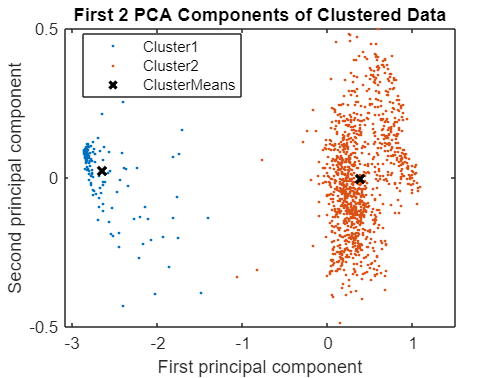

% Perform k-means clustering using specified number of clusters (K value)
K = 2;
[clusterIndices2,centroids2] = kmeans(X,K);
clear K

% Display results

% Display 2D scatter plot (PCA)
figure
[~,score] = pca(X);
clusterMeans = grpstats(score,clusterIndices2,"mean");
h6 = gscatter(score(:,1),score(:,2),clusterIndices2,colormap("lines"));
for i2 = 1:numel(h6)
    h6(i2).DisplayName = strcat("Cluster",h6(i2).DisplayName);
end
clear h6 i2 score
hold on
h6 = scatter(clusterMeans(:,1),clusterMeans(:,2),50,"kx","LineWidth",2);
hold off
h6.DisplayName = "ClusterMeans";
clear h6 clusterMeans
legend;
title("First 2 PCA Components of Clustered Data");
xlabel("First principal component");
ylabel("Second principal component");

test_map=arr_ndvi_sgf(:,:,1);
[h,w,z]=size(test_map);
i_pxl=1;
for idx=1:h
    for jdx=1:w
        if(study_area(idx,jdx)==1)
            test_map(idx,jdx)=clusterIndices2(i_pxl);
            i_pxl=i_pxl+1;
        end
    end
end

Index exceeds the number of array elements. Index must not exceed 1296.


% test_map(test_map==1)=NaN;
% test_map(test_map==2)=0;
% test_map(test_map==3)=0.8;


figure;
f_draw_map(lon_mapa,lat_mapa,lon,lat,test_map,archivo_kml,[1 5],m_colmap('jet','step',10),"NDVI");

f_draw_kml(dir_data,archivo_kml,1,'k');
ax = gca;
ax.FontSize=18; 

uno=sum(test_map(:)==1);
dos=sum(test_map(:)==2);
tres=sum(test_map(:)==3);
cuatro=sum(test_map(:)==4);
cinco=sum(test_map(:)==5);

h1=uno*6.25;
h2=dos*6.25;
h3=tres*6.25;
h4=cuatro*6.25;
h5=cinco*6.25;

fprintf('H1: %.2f\n', h1);
fprintf('H2: %.2f\n', h2);
fprintf('H3: %.2f\n', h3);
fprintf('H4: %.2f\n', h4);
fprintf('H5: %.2f\n', h5);



